clear;clc; 
header = '02000000671D0E2FF45DD1E927A51219D1CA1065C93B0C4E8840290A00000000000000002CD900FC3513260DF5BD2EABFD456CD2B3D2BACE30CC078215A907C045F4992E74749054747B1B1843F740C0';

Check how many characters in the header

format short
h_len = length(header)

h_len = 160

Extract the first 1 to 16 8-characters

w1 =header(1+0*8:8+0*8);
w2 =header(1+1*8:8+1*8);
w3 =header(1+2*8:8+2*8);
w4 =header(1+3*8:8+3*8);
w5 =header(1+4*8:8+4*8);
w6 =header(1+5*8:8+5*8);
w7 =header(1+6*8:8+6*8);
w8 =header(1+7*8:8+7*8);
w9 =header(1+8*8:8+8*8);
w10=header(1+9*8:8+9*8);
w11=header(1+10*8:8+10*8);
w12=header(1+11*8:8+11*8);
w13=header(1+12*8:8+12*8);
w14=header(1+13*8:8+13*8);
w15=header(1+14*8:8+14*8);
w16=header(1+15*8:8+15*8);

Convert the hexadecimal to binary

bw1=hexToBinaryVector(w1,32);
bw2=hexToBinaryVector(w2,32);
bw3=hexToBinaryVector(w3,32);
bw4=hexToBinaryVector(w4,32);
bw5=hexToBinaryVector(w5,32);
bw6=hexToBinaryVector(w6,32);
bw7=hexToBinaryVector(w7,32);
bw8=hexToBinaryVector(w8,32);
bw9=hexToBinaryVector(w9,32);
bw10=hexToBinaryVector(w10,32);
bw11=hexToBinaryVector(w11,32);
bw12=hexToBinaryVector(w12,32);
bw13=hexToBinaryVector(w13,32);
bw14=hexToBinaryVector(w14,32);
bw15=hexToBinaryVector(w15,32);
bw16=hexToBinaryVector(w16,32);


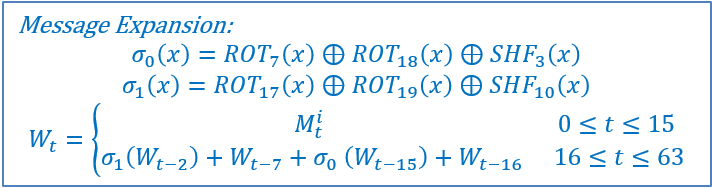

We can find w17 by the above equations, as the following example.

rot7_bw2=[bw2(32-7+1:32),bw2(1:32-7)];
rot18_bw2=[bw2(32-18+1:32),bw2(1:32-18)];
bw2_t(1:3)=0;
shf3_bw2=[bw2_t,bw2(1:32-3)];
sig0_bw2=bitxor(bitxor(rot7_bw2,rot18_bw2),shf3_bw2);
h_sig0_bw2=binaryVectorToHex(sig0_bw2);

rot17_bw15=[bw15(32-17+1:32),bw15(1:32-17)];
rot19_bw15=[bw15(32-19+1:32),bw15(1:32-19)];
bw15_t(1:10)=0;
shf10_bw15=[bw15_t,bw15(1:32-10)];
sig1_bw15=bitxor(bitxor(rot17_bw15,rot19_bw15),shf10_bw15);
h_sig1_bw15=binaryVectorToHex(sig1_bw15)

h_sig1_bw15 = '833D6D7E'


dw17=binaryVectorToDecimal(sig1_bw15) + binaryVectorToDecimal(bw10) + binaryVectorToDecimal(sig0_bw2) + binaryVectorToDecimal(bw1);
w17 = dec2hex(dw17)

w17 = 'C3BCB098'

Try to find w18:

%w18=?